Mask_Image = imread('D:\TA\TA Kak chelli\Mask\BIRADS_2\bus_0191-r_mask.png')

Mask_Image = 384×384×3 uint8 array
Mask_Image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

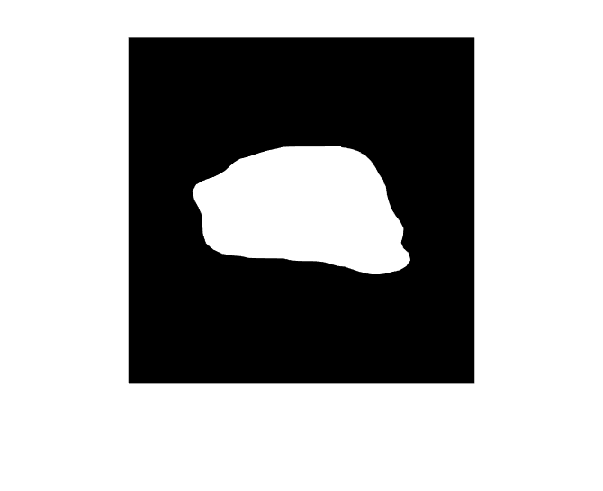

imshow(Mask_Image)

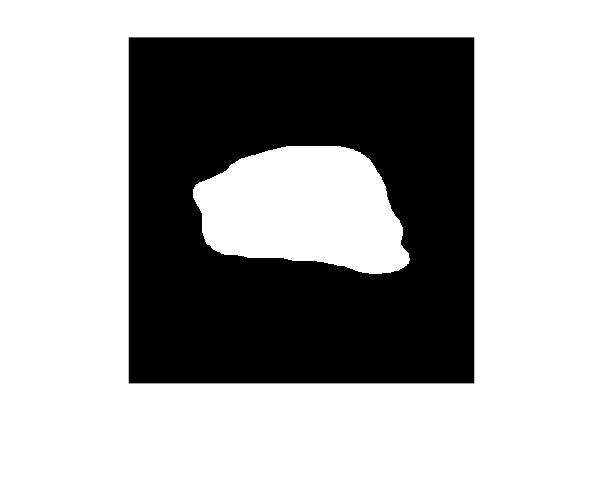

grayMask = rgb2gray(Mask_Image);   % konversi ke grayscale
binaryMask = imbinarize(grayMask); % ubah jadi biner (hitam-putih)
imshow(binaryMask);

binaryMask(:,:,1)

ans = 384×384 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

imshow(binaryMask);

x1 = 50; y1 = 100;  % titik awal
x2 = 200; y2 = 300; % titik akhir
profile = improfile(binaryMask, [x1 x2], [y1 y2]);



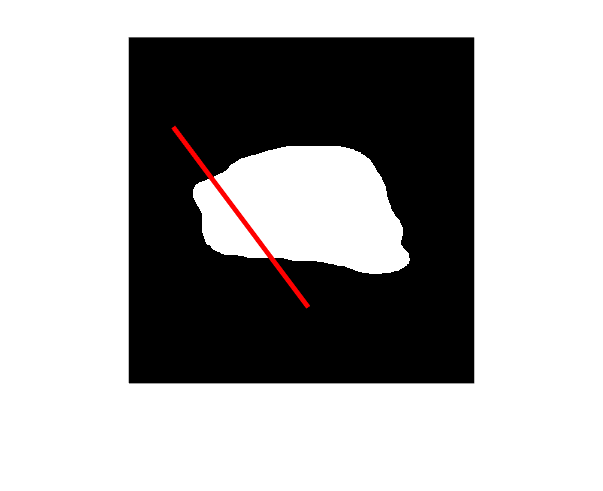

imshow(binaryMask); hold on;
plot([x1 x2], [y1 y2], 'r-', 'LineWidth', 2);

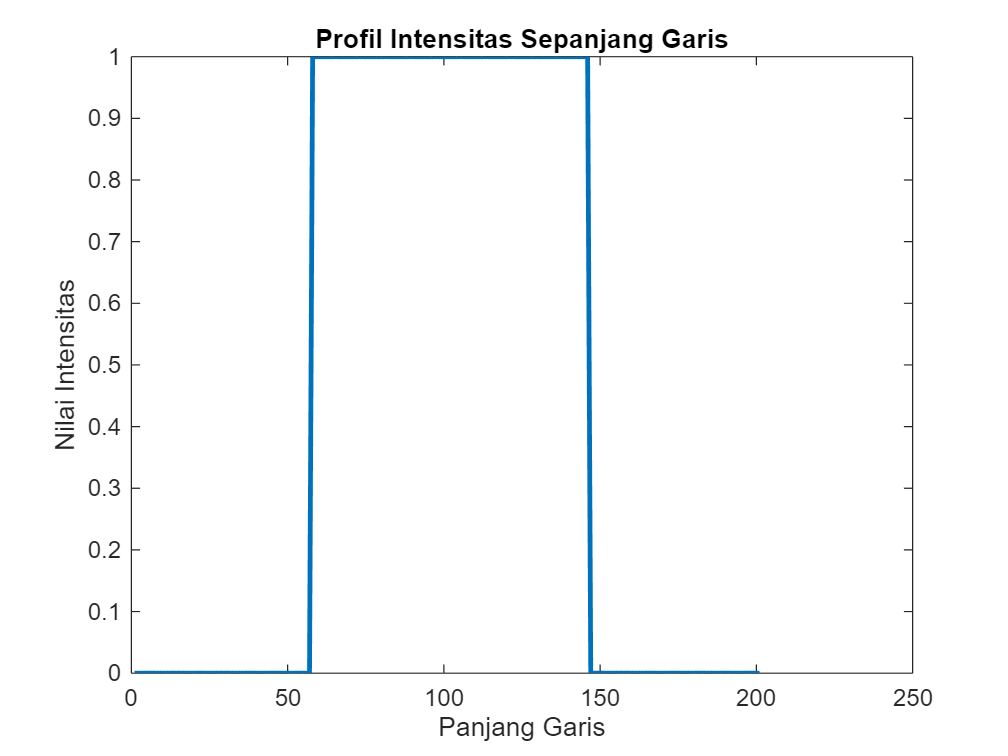

figure ;
plot(profile, 'LineWidth', 2);
title('Profil Intensitas Sepanjang Garis');
xlabel('Panjang Garis');
ylabel('Nilai Intensitas');